This script is for figuring out how to read nwb file, working with data

from Churchland's reaching experiment Jenkins. you can download the file

from here: [https://github.com/dandisets/000128/](https://github.com/dandisets/000128/)

or from here: https://dandiarchive.org/dandiset/000128/0.220113.0400/files?location=sub-Jenkins&page=1

clc; clear;

Read maze task

% Filename and path
data_path = 'C:\Users\asadi\Desktop\AA\Latent_Analysis\000128\sub-Jenkins\sub-Jenkins_ses-full_desc-train_behavior+ecephys.nwb';

[Trials, units, Behavior] = read_mc_maze(data_path);

Get behavioral data

I store behavioral data in a matrix (data_aligned) sized number_of_conditions * time * channel_cols * 30 (** Note that in the 4th dimension, only the first *sum(aligned_trials_type_hand == tr)* has values) 

channel_column = {'hand_pos_x', 'hand_pos_y', 'cursor_pos_x', 'cursor_pos_y', 'eye_pos_x', 'eye_pos_y'};
align_with = 'move_onset_time';
t_range = [-50, 450];

[data_aligned, conds, aligned_trials_type] = align_continuous(Trials, t_range, align_with, channel_column, Behavior);

Find reach angles and assign a color to each

% Get unique combinations of 'trial_type' and 'trial_version'
conds = unique([Trials.trial_type, Trials.trial_version], 'rows');

% Initialize array to store reach angles
reach_angles = [];

% Loop through each unique condition
for cond_idx = 1:size(conds, 1)
    % Create mask to select rows matching current condition
    mask = ismember([Trials.trial_type, Trials.trial_version], conds(cond_idx, :), 'rows');
    
    % Find the active target position for the current condition
    active_target_idx = Trials.active_target(find(mask, 1));  % Get first matching trial's active target index
    active_target_pos = Trials.target_pos{find(mask, 1)};  % Get target position for first matching trial
    
    % Extract the relevant target position (based on active target index)
    target_position = active_target_pos(:, active_target_idx + 1);
    
    reach_angle = atan2(double(target_position(2)), double(target_position(1)));
    
    % Normalize the angle for color mapping
    normalized_angle = reach_angle / (2 * pi) + 0.5;
    
    % Store the color using MATLAB's 'hsv' colormap
    reach_angles = [reach_angles; hsv2rgb(normalized_angle, 1, 1)];  % You can adjust the color if needed
end

Show hand_pos_x for all trials of a given condition

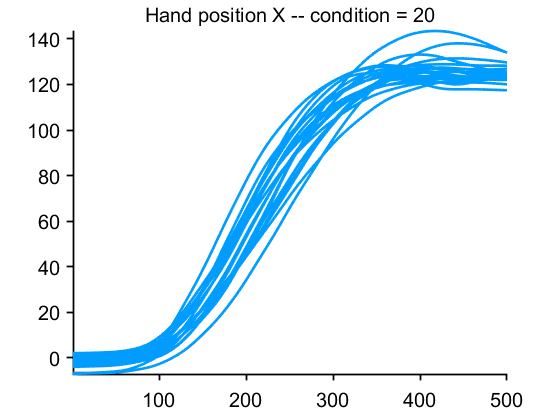

cond = 20;
figure
plot(reshape(data_aligned(cond, :, 1, 1:sum(aligned_trials_type == cond)), size(data_aligned(1, :, 1, 1:sum(aligned_trials_type == cond)), 2), size(data_aligned(1, :, 1, 1:sum(aligned_trials_type == cond)), 4)), 'color', reach_angles(cond, 1, :))
title(['Hand position X -- condition = ', num2str(cond)])
prettify_plot

Plot average hand/cursor/eye trajectory

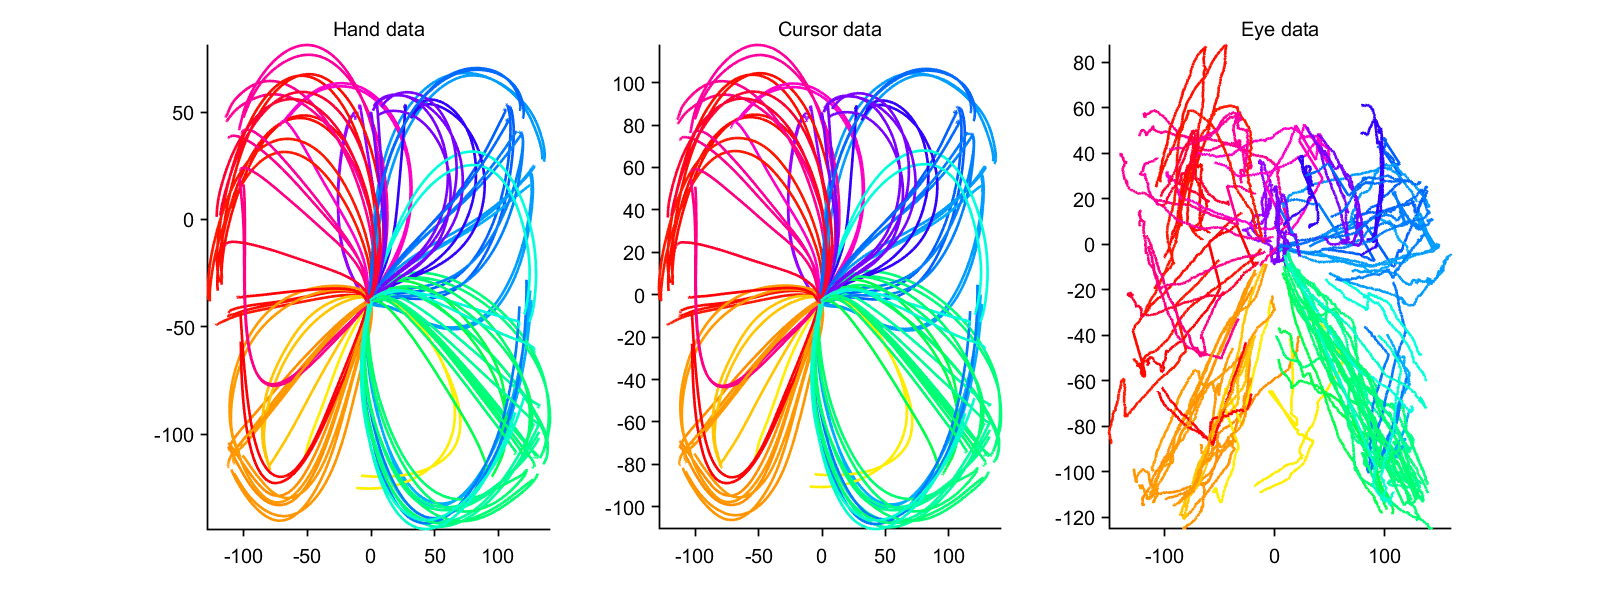

f = figure;
f.Position = [920,386,1603,594];

subplot(1, 3, 1)
for i = 1:size(data_aligned, 1)
    plot(mean(data_aligned(i, :, 1, 1:sum(aligned_trials_type == i)), 4), mean(data_aligned(i, :, 2, 1:sum(aligned_trials_type == i)), 4), 'color', reach_angles(i, 1, :))
    hold on
end
title('Hand data')

subplot(1, 3, 2)
for i = 1:size(data_aligned, 1)
    plot(mean(data_aligned(i, :, 3, 1:sum(aligned_trials_type == i)), 4), mean(data_aligned(i, :, 4, 1:sum(aligned_trials_type == i)), 4), 'color', reach_angles(i, 1, :))
    hold on
end
title('Cursor data')

subplot(1, 3, 3)
for i = 1:size(data_aligned, 1)
    plot(mean(data_aligned(i, :, 5, 1:sum(aligned_trials_type == i)), 4), mean(data_aligned(i, :, 6, 1:sum(aligned_trials_type == i)), 4), 'color', reach_angles(i, 1, :))
    hold on
end
title('Eye data')

prettify_plot

Visualize trials

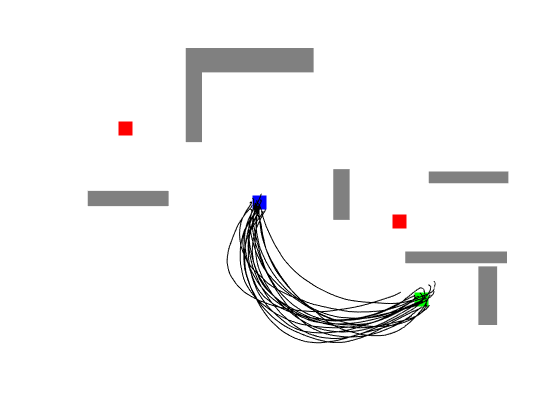

cond = 90;

trs = find(ismember([Trials.trial_type, Trials.trial_version], conds(cond, :), 'rows') == 1);

figure

% Fixation
scatter(0, 0, 200, 'sb', 'filled'); 
hold on
% Plot Targets once (it's the same for a given condition) 
tr = trs(1);

for target = 1:Trials.num_targets(tr)

    tar = Trials.target_pos{tr}(:, target);
    if(Trials.active_target(tr)+1 == target)
        scatter(tar(1), tar(2), 200, 'sg', 'filled'); 
    else
        scatter(tar(1), tar(2), 200, 'sr', 'filled');        
    end

end

% Plot Barriers once (it's the same for a given condition)
for barr = 1:Trials.num_barriers(tr)

    rectangle('Position', Trials.barrier_pos{tr}(:, barr), 'EdgeColor', [0.5, 0.5, 0.5], 'LineWidth', 2, 'FaceColor', [0.5, 0.5, 0.5]);

end

% Plot cursor trajectories for all trials of this condition
for tr = 1:sum(aligned_trials_type == cond)
    plot(data_aligned(cond, :, 3, tr), data_aligned(cond, :, 4, tr), 'k')
end
    
xlim([-150, 200])
ylim([-150, 150])

prettify_addScaleBars

________________________________________________________________________

## Neural **Data**

________________________________________________________________________

Now let's get into the neural data

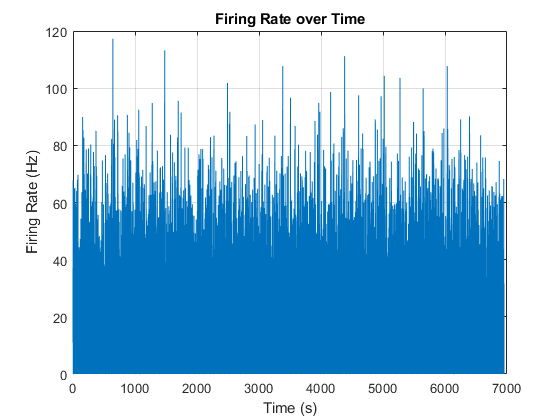

% First plot firing rate of different neurons

figure;

for unit_num = 1:size(units, 1)
    
    spike_times = units.spike_times{unit_num};
    
    % Define the time vector (e.g., 1-second duration, 1 ms resolution)
    t = 0:0.001:Behavior.time(end); % Time vector from 0 to 1.5 seconds with 1 ms resolution
    
    % Define the Gaussian kernel
    kernel_width = 0.05; % 50 ms kernel width
    kernel = normpdf(-3*kernel_width:0.001:3*kernel_width, 0, kernel_width); % Gaussian window
    
    % Create spike train
    spike_train = histcounts(spike_times, [t t(end)+0.001]);
    
    % Convolve the spike train with the kernel
    firing_rate = conv(spike_train, kernel, 'same'); % Smoothed firing rate
    
    % Plot the firing rate over time
    plot(t, firing_rate);
    xlabel('Time (s)');
    ylabel('Firing Rate (Hz)');
    title('Firing Rate over Time');
    grid on;
    
    pause(1)
end

Align spikes to events

% I store neural data in a matrix (data_aligned_FR) sized number_of_conditions * time * number_of_units

align_with = 'move_onset_time';
t_range_prep = [-700, -100];
Kernel = 'noncasual';
gauss_width = 50;

neural_prep = align_fr(Trials, units, t_range_prep, align_with, Kernel, gauss_width);

align_with = 'move_onset_time';
t_range_exe = [-50, 300];
Kernel = 'noncasual';
gauss_width = 50;

neural_exe = align_fr(Trials, units, t_range_exe, align_with, Kernel, gauss_width);

### Perform PCA

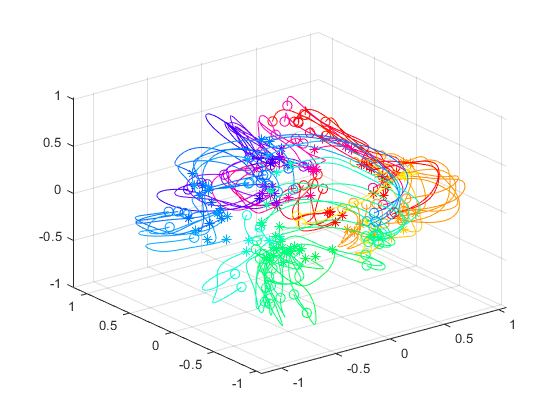

% neural_exe is a 3D matrix (number_of_conditions x time x number_of_units)

% Calculate the mean across the first dimension (conditions)
n_mean = mean(neural_exe, 1);

n_range = max(reshape(neural_exe, [], size(neural_exe, 3))) - min(reshape(neural_exe, [], size(neural_exe, 3)));
% n_range is now 1 x number_of_units

% Scale the data
X = (neural_exe - repmat(n_mean, size(neural_exe, 1), 1, 1)) ./ repmat(reshape(n_range + 5, 1, 1, size(n_range + 5, 2)) , size(neural_exe, 1), size(neural_exe, 2), 1);

X_reshaped = reshape(X, [], size(X, 3));
% Calculate the mean across the first dimension (number_of_conditions)
mean_X = mean(X_reshaped, 1);
mean_X_normal = X_reshaped - repmat(mean_X, size(X_reshaped, 1), 1);
% Perform SVD on the reshaped matrix
[U, S, Vt] = svd(mean_X_normal, 'econ'); % 'econ' gives the economy size decomposition
num_compo = 3; % Specify the desired number of components
components = Vt(:, 1:num_compo); % Select the first 'num_latent' components
% Calculate the explained variance
variance_explained = (diag(S).^2) / sum(diag(S).^2); % Variance explained by each component
variance = (diag(S).^2) / (size(X, 3) - 1); % Variance for each component

Latent = mean_X_normal * components;
Latent = reshape(Latent, size(X, 1), size(X, 2), num_compo);

figure

for i = 1:108
    
    plot3(Latent(i, :, 1), Latent(i, :, 2), Latent(i, :, 3), 'color', reach_angles(i, 1, :))
    scatter3(Latent(i, 1, 1), Latent(i, 1, 2), Latent(i, 1, 3), 50, reshape(reach_angles(i, 1, :), 1, 3), 'o')
    scatter3(Latent(i, end, 1), Latent(i, end, 2), Latent(i, end, 3), 50, reshape(reach_angles(i, 1, :), 1, 3), '*')
    hold on
    
end

### Perform jPCA

addpath 'C:\Users\asadi\Documents\jPCA_libraries\fromMarksLibraries' -END
addpath 'C:\Users\asadi\Documents\jPCA_libraries\CircStat2010d' -END

jPCA_params.softenNorm = 5; % how each neuron's rate is normized, see below=
jPCA_params.suppressBWrosettes = true; % these are useful sanity plots, but lets ignore them for now 
jPCA_params.suppressHistograms = true; % these are useful sanity plots, but lets ignore them for now

align_with = 'move_onset_time';
t_range_exe = [-50, 150];
Kernel = 'noncasual';
gauss_width = 50;

neural_exe = align_fr(Trials, units, t_range_exe, align_with, Kernel, gauss_width);

% Prepare data
[n_conditions, n_time, n_neurons] = size(neural_exe);

% Initialize the struct
Data = struct();

% Loop over each condition to populate the struct
for i = 1:n_conditions
    % Store the time-neuron matrix for each condition
    Data(i).A = squeeze(neural_exe(i, :, :)); % Extract time*neuron matrix
    Data(i).times = t_range_exe(1):t_range_exe(end); % Assuming time is indexed from 1 to 'time'
end

times = t_range_exe(1):t_range_exe(end); % -50 to 150 ms w.r.t 'neural movement onset'
jPCA_params.numPCs = 6; % default anyway, but best to be specific
[Projection, Summary] = jPCA_v2(Data, times, jPCA_params);

mild warning!!!!: you are using a short time base which might make the computation of the derivative a bit less reliable
eigenvalues of Mskew: 
                  0.006i     -0.006i 
                  0.002i     -0.002i 
                  0.001i     -0.001i 
% R^2 for Mbest (all 6 dims):   0.43
% R^2 for Mskew (all 6 dims):   0.37  <<---------------
% R^2 for Mbest (primary 2D plane):   0.61
% R^2 for Mskew (primary 2D plane):   0.58  <<---------------


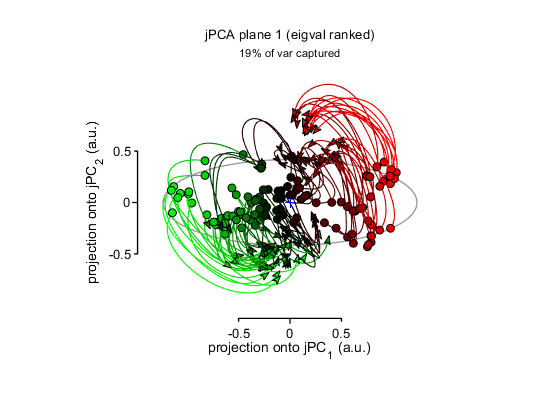

phaseSpace(Projection, Summary); % makes the plot

disp(['Var explained by 6 jPCs = ', num2str(sum(Summary.varCaptEachJPC(1:6)))])

Var explained by 6 jPCs = 0.56306


### Perform dPCA

### Factor Analysis

Plot firing rate for a condition

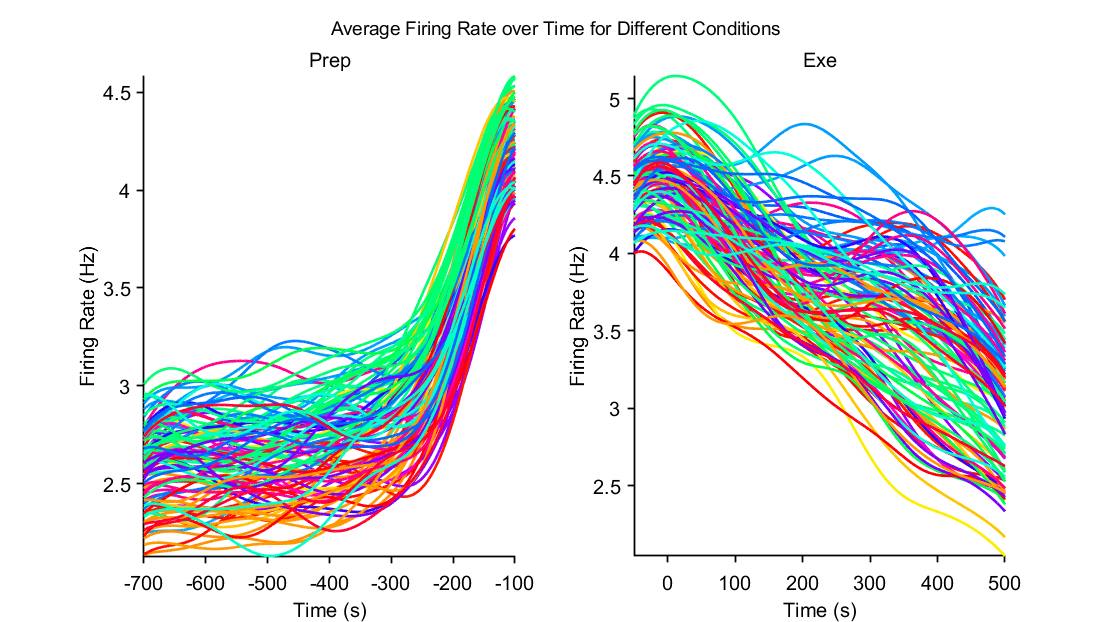

align_with = 'move_onset_time';
t_range_prep = [-700, -100];
Kernel = 'noncasual';
gauss_width = 50;

neural_prep = align_fr(Trials, units, t_range_prep, align_with, Kernel, gauss_width);

align_with = 'move_onset_time';
t_range_exe = [-50, 500];
Kernel = 'noncasual';
gauss_width = 50;

neural_exe = align_fr(Trials, units, t_range_exe, align_with, Kernel, gauss_width);

f = figure;
f.Position = [1000,356,1111,622];

subplot(1, 2, 1)
for cond = 1:size(neural_prep, 1)
    plot(t_range_prep(1):t_range_prep(2), mean(neural_prep(cond, :, :), 3)', 'color', reach_angles(cond, 1, :))
    hold on
end
xlabel('Time (s)');
ylabel('Firing Rate (Hz)');
title('Prep')
xlim(t_range_prep)

subplot(1, 2, 2)
for cond = 1:size(neural_exe, 1)
    plot(t_range_exe(1):t_range_exe(2), mean(neural_exe(cond, :, :), 3)', 'color', reach_angles(cond, 1, :))
    hold on
end
xlim(t_range_exe)
xlabel('Time (s)');
ylabel('Firing Rate (Hz)');
title('Exe')

sgtitle('Average Firing Rate over Time for Different Conditions');
prettify_plot

Correlation matrix

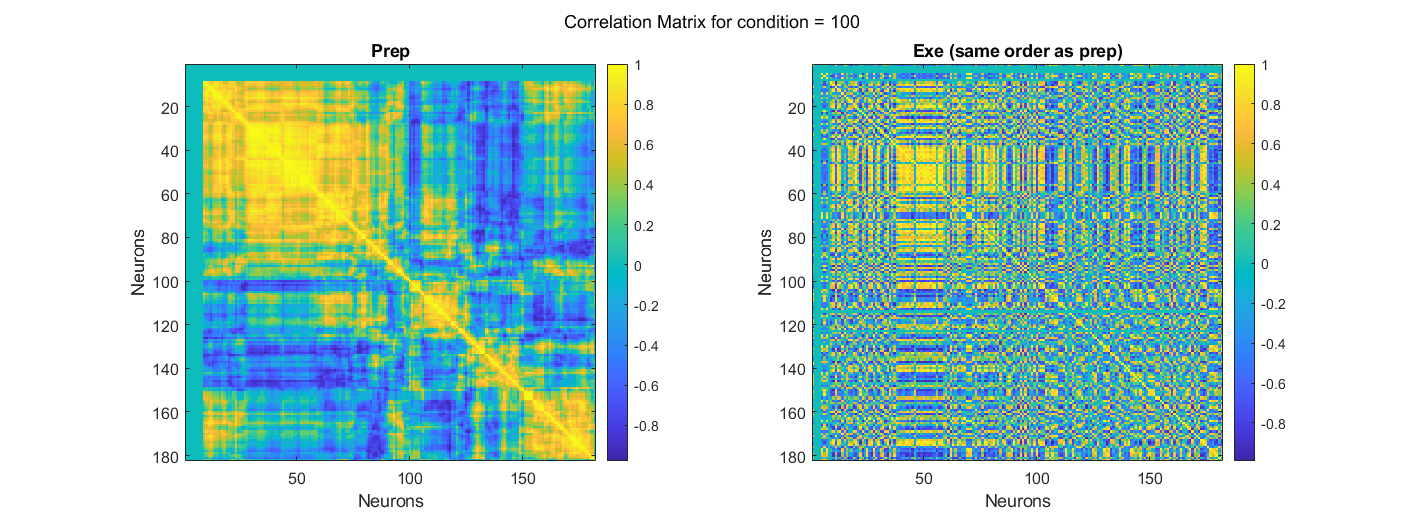

f = figure;
f.Position = [1000,463,1424,515];

cond = 100;

% For prep epoch
neural_prep_allcond = reshape(neural_prep(cond, :, :), [], size(neural_prep, 3));

subplot(1, 2, 1)
corr_matrix = corr(neural_prep_allcond);

corr_matrix(isnan(corr_matrix)) = 0;
dist_matrix = 1 - corr_matrix;
dist_matrix(1:size(dist_matrix, 1) + 1:end) = 0;
condensed_dist_matrix = squareform(dist_matrix); 
Z = linkage(condensed_dist_matrix, 'average');
dend_order = optimalleaforder(Z, condensed_dist_matrix);
reordered_corr_matrix = corr_matrix(dend_order, dend_order);

imagesc(reordered_corr_matrix);
colorbar;
title('Reordered Neuron Correlation Matrix');
xlabel('Neurons');
ylabel('Neurons');
title('Prep');
set(gca, 'FontSize', 12); % Adjust font size for better visibility

% For exe epoch
neural_exe_allcond = reshape(neural_exe(cond, :, :), [], size(neural_exe, 3));

subplot(1, 2, 2)
corr_matrix = corr(neural_exe_allcond);

corr_matrix(isnan(corr_matrix)) = 0;
dist_matrix = 1 - corr_matrix;
dist_matrix(1:size(dist_matrix, 1) + 1:end) = 0;
condensed_dist_matrix = squareform(dist_matrix); 
Z = linkage(condensed_dist_matrix, 'average');
% dend_order = optimalleaforder(Z, condensed_dist_matrix);
reordered_corr_matrix = corr_matrix(dend_order, dend_order);

imagesc(reordered_corr_matrix);
colorbar;
title('Reordered Neuron Correlation Matrix');
xlabel('Neurons');
ylabel('Neurons');
title('Exe (same order as prep)');
set(gca, 'FontSize', 12); % Adjust font size for better visibility

sgtitle(['Correlation Matrix for condition = ', num2str(cond)])

## Find Orthogonal Subspaces for Prep and Exe

"maxvar_subspaces" function is from 2016 Gamaleldin F. Elsayed and John P. Cunningham

% Scale the data
n_mean = mean(neural_exe, 1);
n_range = max(reshape(neural_exe, [], size(neural_exe, 3))) - min(reshape(neural_exe, [], size(neural_exe, 3)));
X_exe = (neural_exe - repmat(n_mean, size(neural_exe, 1), 1, 1)) ./ repmat(reshape(n_range + 5, 1, 1, size(n_range + 5, 2)) , size(neural_exe, 1), size(neural_exe, 2), 1);

n_mean = mean(neural_prep, 1);
n_range = max(reshape(neural_prep, [], size(neural_prep, 3))) - min(reshape(neural_prep, [], size(neural_prep, 3)));
X_prep = (neural_prep - repmat(n_mean, size(neural_prep, 1), 1, 1)) ./ repmat(reshape(n_range + 5, 1, 1, size(n_range + 5, 2)) , size(neural_prep, 1), size(neural_prep, 2), 1);

X_exe_1 = reshape(X_exe(1, :, :), size(X_exe, 2), size(X_exe, 3));
X_prep_1 = reshape(X_prep(1, :, :), size(X_prep, 2), size(X_prep, 3));

find low-dimensional neural manifold for prep and exe from the data of the first condition

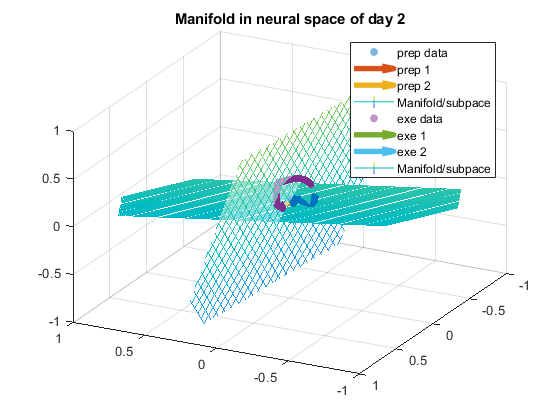

[U_exe, S_exe, V_exe] = svd(X_exe_1');
[U_prep, S_prep, V_prep] = svd(X_prep_1');

% Now keep only a few of the basis vectors in U: the first d dimensions, 
% corresponding to leading eigenvalues (Matlab's svd function orders basis 
% vectors by eigenvalues automatically). d is the dimensionality 
% of the low-dimensional neural manifold embedded in emperical neural space.

% Set 'flat dimension' d
d = 2;

% Select first d basis vectors from U_n and U_m
U_exe_tilde = U_exe(:, 1:d);
U_prep_tilde = U_prep(:, 1:d);

us = {U_prep_tilde, U_exe_tilde};
uss = {X_prep_1', X_exe_1'};

cells{1} = [1, 2, 3];
cells{2} = [1, 2, 3];
    
figure
for currDay = 1:2
    
    hold on;    

    data_plot = uss{currDay};
    
    scatter3(data_plot(1, 2:end-1), data_plot(2, 2:end-1), data_plot(3, 2:end-1), 30, 'filled')
    for currDir = 1:2
        quiver3(0, 0, 0, ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(1), currDir), ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(2), currDir), ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(3), currDir), 0, ...
            'LineWidth', 4);
    end
    
    % Plot plane spanned by first two principal directions
    fmesh(@(s,t) us{currDay}(cells{currDay}(1),1)*s+us{currDay}(cells{currDay}(1),2)*t, ...
        @(s,t) us{currDay}(cells{currDay}(2),1)*s+us{currDay}(cells{currDay}(2),2)*t, ...
        @(s,t) us{currDay}(cells{currDay}(3),1)*s+us{currDay}(cells{currDay}(3),2)*t, ...
        [-10, 10])
    alpha(0.5);
    hold off;
    % Set plot layout properties
    legend('prep data', 'prep 1',...
        'prep 2', 'Manifold/subpace', 'exe data', 'exe 1',...
        'exe 2', 'Manifold/subpace');
    
    xlim([-1,1]);
    ylim([-1,1]);
    zlim([-1,1]);
    view([-152.70 30.60])
    grid on;
    title(['Manifold in neural space of day ' num2str(currDay)]);
end

% Calculate inner products between basis vectors in U_n_tilde and U_m_tilde
innerProducts = U_prep_tilde' * U_exe_tilde;

% Do another svd on the inner product between basis vectors
[U_ip, S_ip, V_ip] = svd(innerProducts);

% Calculate the angles between hyperplanes from the diagonal of S_ip, which
% holds the ordered cosines of principal angles
angles = rad2deg(acos(diag(S_ip)));
disp(['Angles between hyperplanes are '...
    num2str(angles(1), 2) ', ' num2str(angles(2), 2)]);

Angles between hyperplanes are 64, 71


DataStruct(1).A = reshape(X_prep, size(X_prep, 1)*size(X_prep, 2), size(X_prep, 3));
DataStruct(1).dim = 3;
DataStruct(2).A = reshape(X_exe, size(X_exe, 1)*size(X_exe, 2), size(X_exe, 3));
DataStruct(2).dim = 3;

[QSubspaces] = maxvar_subspaces(DataStruct);

(Stiefel manifold trust region opt completed on maxvar_subspaces_objfn in 9 iterations, objective optimized from 0.0199946 to 0.0184385)
Total iterations:    10 of 10000,      Final Obj. Value: 0.981561,  Total time: (0.00521 sec)


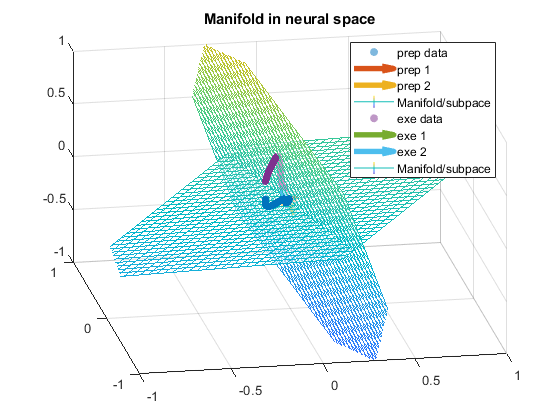


Qi1 = QSubspaces(1).Q; % identified orthonormal basis for subspace 1
Qi2 = QSubspaces(2).Q; % identified orthonormal basis for subspace 2

us = {Qi1(:, 1:2), Qi2(:, 1:2)};

uss = {X_prep_1', X_exe_1'};

cells{1} = [1, 2, 3];
cells{2} = [1, 2, 3];

figure
for currDay = 1:2
    
    hold on;    

    data_plot = uss{currDay};
    
    scatter3(data_plot(1, 2:end-1), data_plot(2, 2:end-1), data_plot(3, 2:end-1), 30, 'filled') 

    for currDir = 1:2
        quiver3(0, 0, 0, ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(1), currDir), ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(2), currDir), ...
            max(abs(data_plot(:)))*us{currDay}(cells{currDay}(3), currDir), 0, ...
            'LineWidth', 4);
    end
    
    % Plot plane spanned by first two principal directions
    fmesh(@(s,t) us{currDay}(cells{currDay}(1),1)*s+us{currDay}(cells{currDay}(1),2)*t, ...
        @(s,t) us{currDay}(cells{currDay}(2),1)*s+us{currDay}(cells{currDay}(2),2)*t, ...
        @(s,t) us{currDay}(cells{currDay}(3),1)*s+us{currDay}(cells{currDay}(3),2)*t, ...
        [-10, 10])
    alpha(0.5);
    hold off;
    % Set plot layout properties
    legend('prep data', 'prep 1',...
        'prep 2', 'Manifold/subpace', 'exe data', 'exe 1',...
        'exe 2', 'Manifold/subpace');
    
    xlim([-1,1]);
    ylim([-1,1]);
    zlim([-1,1]);
    view([-10.20 28.20])
    grid on;
    title(['Manifold in neural space']);
end


% Calculate inner products between basis vectors in U_n_tilde and U_m_tilde
innerProducts = Qi1(:, 1:2)' * Qi2(:, 1:2);

% Do another svd on the inner product between basis vectors
[U_ip, S_ip, V_ip] = svd(innerProducts);

% Calculate the angles between hyperplanes from the diagonal of S_ip, which
% holds the ordered cosines of principal angles
angles = rad2deg(acos(diag(S_ip)));
disp(['Angles between hyperplanes are '...
    num2str(angles(1), 2) ', ' num2str(angles(2), 2)]);

Angles between hyperplanes are 90, 90


Plot variance explained by each subspace on a larger epoch

align_with = 'target_on_time';
t_range_plan = [-50, 1000];
Kernel = 'noncasual';
gauss_width = 50;

neural_plan = align_fr(Trials, units, t_range_plan, align_with, Kernel, gauss_width);

align_with = 'move_onset_time';
t_range_move = [-1000, 500];
Kernel = 'noncasual';
gauss_width = 50;

neural_move = align_fr(Trials, units, t_range_move, align_with, Kernel, gauss_width);

n_mean = mean(neural_plan, 1);
n_range = max(reshape(neural_plan, [], size(neural_plan, 3))) - min(reshape(neural_plan, [], size(neural_plan, 3)));
X_plan = (neural_plan - repmat(n_mean, size(neural_plan, 1), 1, 1)) ./ repmat(reshape(n_range + 5, 1, 1, size(n_range + 5, 2)) , size(neural_plan, 1), size(neural_plan, 2), 1);

n_mean = mean(neural_move, 1);
n_range = max(reshape(neural_move, [], size(neural_move, 3))) - min(reshape(neural_move, [], size(neural_move, 3)));
X_move = (neural_move - repmat(n_mean, size(neural_move, 1), 1, 1)) ./ repmat(reshape(n_range + 5, 1, 1, size(n_range + 5, 2)) , size(neural_move, 1), size(neural_move, 2), 1);

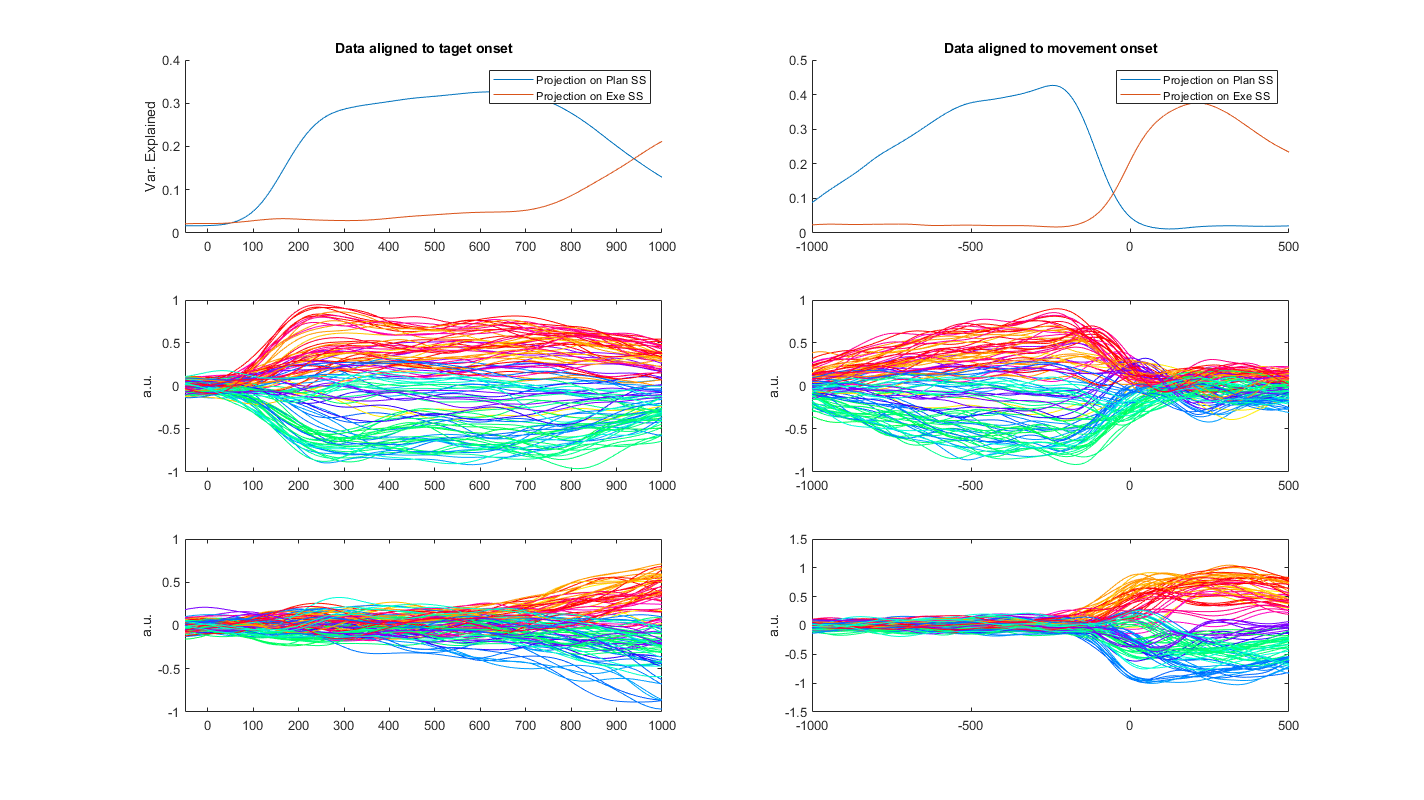

f = figure;
f.Position = [1000,200,1424,800];

subplot(3, 2, 1); hold on

tot_var = sum(reshape(var(X_plan, 0, 1), size(var(X_plan, 0, 1), 2), size(var(X_plan, 0, 1), 3)), 2);

[dim1, dim2, dim3] = size(X_plan);
reshaped_data = reshape(X_plan, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi1;  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi1, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, new_dim);
var_along_dim2 = reshape(var(data_projected_3D, 0, 1), size(var(data_projected_3D, 0, 1), 2), size(var(data_projected_3D, 0, 1), 3));  % Variance along the second dimension
sum_var = sum(var_along_dim2, 2);  % Summing over the first dimension
tot_var_projected = sum_var ./ tot_var;

plot(t_range_plan(1):t_range_plan(2), tot_var_projected)
xlim([t_range_plan(1), t_range_plan(2)])
title('Data aligned to taget onset')
tot_var = sum(reshape(var(X_plan, 0, 1), size(var(X_plan, 0, 1), 2), size(var(X_plan, 0, 1), 3)), 2);

[dim1, dim2, dim3] = size(X_plan);
reshaped_data = reshape(X_plan, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi2;  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi2, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, new_dim);
var_along_dim2 = reshape(var(data_projected_3D, 0, 1), size(var(data_projected_3D, 0, 1), 2), size(var(data_projected_3D, 0, 1), 3));  % Variance along the second dimension
sum_var = sum(var_along_dim2, 2);  % Summing over the first dimension
tot_var_projected = sum_var ./ tot_var;

plot(t_range_plan(1):t_range_plan(2), tot_var_projected)
xlim([t_range_plan(1), t_range_plan(2)])
ylabel('Var. Explained')
legend('Projection on Plan SS', 'Projection on Exe SS', 'Location','northeast')

subplot(3, 2, 2); hold on

tot_var = sum(reshape(var(X_move, 0, 1), size(var(X_move, 0, 1), 2), size(var(X_move, 0, 1), 3)), 2);

[dim1, dim2, dim3] = size(X_move);
reshaped_data = reshape(X_move, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi1;  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi1, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, new_dim);
var_along_dim2 = reshape(var(data_projected_3D, 0, 1), size(var(data_projected_3D, 0, 1), 2), size(var(data_projected_3D, 0, 1), 3));  % Variance along the second dimension
sum_var = sum(var_along_dim2, 2);  % Summing over the first dimension
tot_var_projected = sum_var ./ tot_var;

plot(t_range_move(1):t_range_move(2), tot_var_projected)
title('Data aligned to movement onset')
xlim([t_range_move(1), t_range_move(2)])
tot_var = sum(reshape(var(X_move, 0, 1), size(var(X_move, 0, 1), 2), size(var(X_move, 0, 1), 3)), 2);

[dim1, dim2, dim3] = size(X_move);
reshaped_data = reshape(X_move, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi2;  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi2, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, new_dim);
var_along_dim2 = reshape(var(data_projected_3D, 0, 1), size(var(data_projected_3D, 0, 1), 2), size(var(data_projected_3D, 0, 1), 3));  % Variance along the second dimension
sum_var = sum(var_along_dim2, 2);  % Summing over the first dimension
tot_var_projected = sum_var ./ tot_var;

plot(t_range_move(1):t_range_move(2), tot_var_projected)
legend('Projection on Plan SS', 'Projection on Exe SS', 'Location','northeast')

subplot(3, 2, 3)
[dim1, dim2, dim3] = size(X_plan);
reshaped_data = reshape(X_plan, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi1(:, 1);  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi1, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, 1);

for cond = 1:size(data_projected_3D, 1)
    plot(t_range_plan(1):t_range_plan(2), data_projected_3D(cond, :), 'color', reach_angles(cond, 1, :))
    hold on
end
ylabel('a.u.')
xlim([t_range_plan(1), t_range_plan(2)])

subplot(3, 2, 4)
[dim1, dim2, dim3] = size(X_move);
reshaped_data = reshape(X_move, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi1(:, 1);  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi1, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, 1);

for cond = 1:size(data_projected_3D, 1)
    plot(t_range_move(1):t_range_move(2), data_projected_3D(cond, :), 'color', reach_angles(cond, 1, :))
    hold on
end
ylabel('a.u.')
xlim([t_range_move(1), t_range_move(2)])

subplot(3, 2, 5)
[dim1, dim2, dim3] = size(X_plan);
reshaped_data = reshape(X_plan, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi2(:, 1);  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi2, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, 1);

for cond = 1:size(data_projected_3D, 1)
    plot(t_range_plan(1):t_range_plan(2), data_projected_3D(cond, :), 'color', reach_angles(cond, 1, :))
    hold on
end
ylabel('a.u.')
xlim([t_range_plan(1), t_range_plan(2)])

subplot(3, 2, 6)
[dim1, dim2, dim3] = size(X_move);
reshaped_data = reshape(X_move, dim1 * dim2, dim3);  % Resulting size is (dim1*dim2, dim3)
data_projected = reshaped_data * Qi2(:, 1);  % Resulting size is (dim1*dim2, new_dim)
new_dim = size(Qi2, 2);  % The new third dimension after projection
data_projected_3D = reshape(data_projected, dim1, dim2, 1);

for cond = 1:size(data_projected_3D, 1)
    plot(t_range_move(1):t_range_move(2), data_projected_3D(cond, :), 'color', reach_angles(cond, 1, :))
    hold on
end
ylabel('a.u.')
xlim([t_range_move(1), t_range_move(2)])

#### Functions:

function data_aligned = align_fr(Trials, units, t_range, align_with, Kernel, gauss_width, fs)

    % I return average firing rate for each condition
    if nargin < 7
            fs = 1000;
    end
    
    % find unique conditions (each trial type has different versions)
    conds = unique([Trials.trial_type, Trials.trial_version], 'rows');
    data_aligned = zeros(size(conds, 1), t_range(2) - t_range(1) + 1, size(units, 1)); % 30 is a max for the number of trials I store

    if(strcmp(Kernel, 'noncasual'))

%         gauss_width = 50;   % Window size 50 ms (Lara: 20 ms)
        dt = 1/1000;   % Step size
        bin_width = dt * 1000;
        gauss_bin_std = gauss_width / bin_width;
        win_len = int32(6 * gauss_bin_std);
        window = gausswin(win_len, win_len/gauss_bin_std/2);
        window = window / sum(window);
        pad = 100; %50 ms padding

    elseif(strcmp(Kernel, 'casual'))

        growth = 1;
        decay = 20;
        A = [];
        for i = 0:1:100  % A 100 ms function
            A(end+1,1) = i;
            A(end,2) = (1 - exp(i*-1/growth)) .* (exp(i*-1/decay));
        end
        B = cumsum(A,1);    % Sums along columns to extract area
        C = B(size(B,1),size(B,2)); % Value in last row and column of B is the area of the curve
        window = [A(:,2)/C];
        pad = 50; %50 ms padding

    end

    timeRange = t_range(1)-pad:t_range(2)+pad;

    for cond_idx = 1:size(conds, 1)

        trs = find(ismember([Trials.trial_type, Trials.trial_version], conds(cond_idx, :), 'rows') == 1);

        ev = Trials.(align_with)(trs);

        data_aligned_all = zeros(timeRange(end) - timeRange(1)+1-2*pad, size(units, 1));

        for unit = 1:size(units, 1)

            spikeMatrix = zeros(length(trs), timeRange(end)-timeRange(1)+1);

            for i = 1:length(trs)

                spikes = units.spike_times{unit};
                tr_idxs = find(spikes >= ev(i) + timeRange(1)/fs & spikes <= ev(i) + timeRange(end)/fs);

                % Iterate over each spike time in the current trial
                for j = 1:length(tr_idxs)
                     roundedSpikeTime = round((spikes(tr_idxs(j)) - ev(i))*fs);

                    % Convert the spike time to the appropriate index in the new matrix
                    spikeIndex = find(timeRange(1):timeRange(end) == roundedSpikeTime);

                    if ~isempty(spikeIndex)
                        % Set the corresponding cell in the new matrix to 1
                        spikeMatrix(i, spikeIndex) = 1;
                    end
                end
            end

            baSm = conv2(window',1,spikeMatrix', 'same')'./0.001;
            baSm = baSm(:, pad+1:end-pad);

            data_aligned_all(:, unit) = mean(baSm, 1);

        end

        data_aligned(cond_idx, :, :) = data_aligned_all;

    end

end

function [data_aligned, conds, aligned_trials_type] = align_continuous(Trials, t_range, align_with, channel_column, Behavior, fs)

    % I store behavioral data in a matrix sized number_of_conditions * time * channel_cols * 30 (** Note that in the 4th dimension, only the first *sum(aligned_trials_type_hand == tr)* has values) 

    if nargin < 6
        fs = 1000;
    end
    
    % find unique conditions (each trial type has different versions)
    conds = unique([Trials.trial_type, Trials.trial_version], 'rows');
    data_aligned = zeros(size(conds, 1), t_range(2) - t_range(1), length(channel_column), 30); % 30 is a max for the number of trials I store

    aligned_trials_type = zeros(1, length(Trials.trial_type));
    
    for cond_idx = 1:size(conds, 1)

        trs = find(ismember([Trials.trial_type, Trials.trial_version], conds(cond_idx, :), 'rows') == 1);

        ev = Trials.(align_with)(trs);

        data_aligned_all = zeros(t_range(2) - t_range(1), length(channel_column), length(trs));

        for i = 1:length(trs)
            tr_idxs = find(Behavior.time >= ev(i) + t_range(1)/fs & Behavior.time <= ev(i) + t_range(2)/fs);

            for col = 1:length(channel_column)
                 data_aligned_all(:, col, i) = Behavior.(channel_column{col})(tr_idxs(1:(t_range(2) - t_range(1))));
            end
        end

        aligned_trials_type = [aligned_trials_type, cond_idx*ones(1, length(trs))];
            
        data_aligned(cond_idx, :, :, 1:length(trs)) = data_aligned_all;
    end
    
end